# URI machine learning benchmark

One of the experiments in the CLASSIX paper [1], compares several clustering algorithms on the URI machine learning repository [2]. The Python code that generated these results, together with all the used hyperparameters, is available in the CLASSIX GitHub repository: [https://github.com/nla-group/classix/blob/master/exp/run_real_world.py](https://github.com/nla-group/classix/blob/master/exp/run_real_world.py) 

Let's recreate the column "CLASSIX (distance)" in Table 2 of [1]. Instead of using Python, we'll use the MATLAB implementation of CLASSIX.

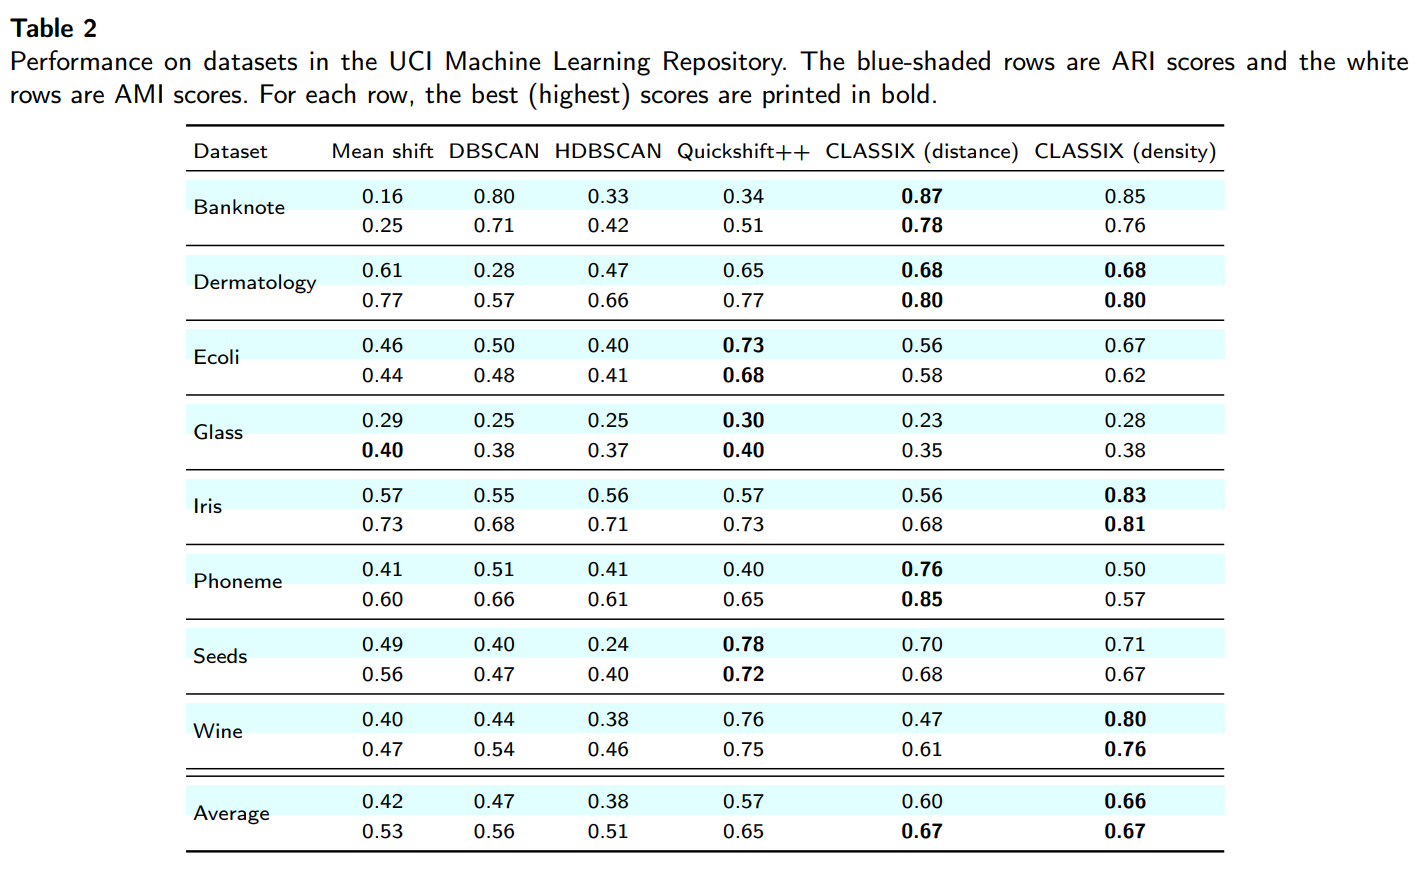

First, we create a function handle to compute the adjusted RAND index (ARI).

addpath ..
ari = @(a,b) rand_index(double(a),double(b),'adjusted');

Now we run each of the datasets, using as parameters the ones used in the CLASSIX paper.

load('../data/Banknote.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.21,41);
fprintf('Banknote runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Banknote runtime: 0.021 seconds - classes: 2 - ARI: 0.87


load('../data/Dermatology.mat')
ind = find(~isnan(sum(data,2))); % data has 8 rows with NaN's
data = data(ind,:); labels = label(ind); % remove then
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.4,4);
fprintf('Dermatology runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Dermatology runtime: 0.019 seconds - classes: 7 - ARI: 0.00


load('../data/Ecoli.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.3,4);
fprintf('Ecoli runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Ecoli runtime: 0.013 seconds - classes: 7 - ARI: 0.56


load('../data/Glass.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.725,1);
fprintf('Glass runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Glass runtime: 0.009 seconds - classes: 26 - ARI: 0.23


load('../data/Iris.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.225,4);
fprintf('Iris runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Iris runtime: 0.009 seconds - classes: 4 - ARI: 0.56


load('../data/Phoneme.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.445,8);
fprintf('Phoneme runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Phoneme runtime: 2.228 seconds - classes: 4 - ARI: 0.76


load('../data/Seeds.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.15,9);
fprintf('Seeds runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Seeds runtime: 0.014 seconds - classes: 3 - ARI: 0.70


load('../data/Wine.mat')
data = (data - mean(data))./std(data); % z-normalization 
tic
label = classix(data,0.425,4);
fprintf('Wine runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc, length(unique(label)), ari(labels,label))

Wine runtime: 0.012 seconds - classes: 2 - ARI: 0.47


The results are in agreement with the paper, giving us confidence that the MATLAB implementation is equivalent to the Python one. Almost all clusterings were run in just a couple of milliseconds. Only the Phoneme dataset is slightly harder.

## Learn more about CLASSIX?

CLASSIX is a fast and memory-efficient clustering algorithm which produces explainable results. If you'd like to learn more about CLASSIX, here are a couple of online resources:

- arXiv paper: [Fast and explainable clustering based on sorting (arxiv.org)](https://arxiv.org/abs/2202.01456)

- Python code: [Fast and explainable clustering based on sorting (github.com)](https://github.com/nla-group/classix)

- YouTube video: [CLASSIX - Fast and explainable clustering based on sorting - YouTube](https://www.youtube.com/watch?v=K94zgRjFEYo)

## References

[1] C. Chen and S. Güttel. "Fast and explainable clustering based on sorting." arXiv: [https://arxiv.org/abs/2202.01456](https://arxiv.org/abs/2202.01456), 2022.

[2] D. Dua and C. Graff. "UCI machine learning repository." URL: [http://archive.ics.uci.edu/ml](http://archive.ics.uci.edu/ml), 2017.